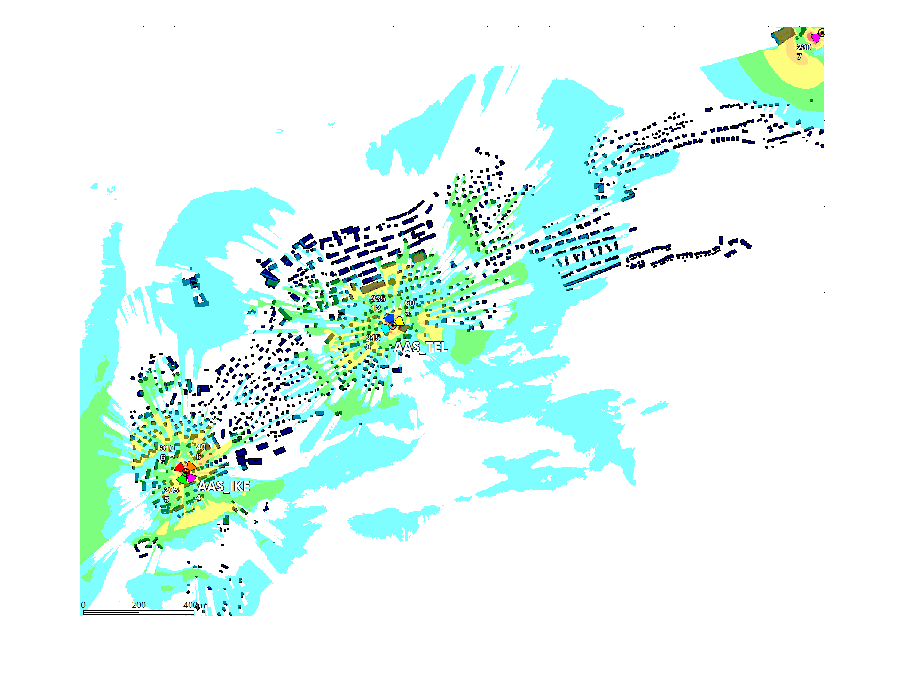

mc = imread('aas n78 sig cropped.png');
imshow(mc);

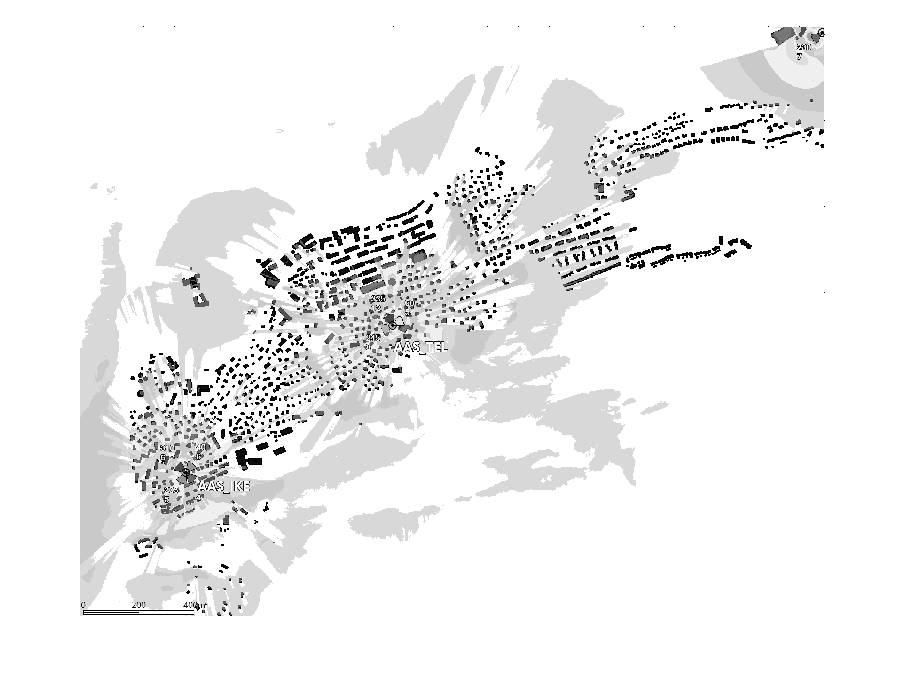

Igr = rgb2gray(mc);
imshow(Igr, []);

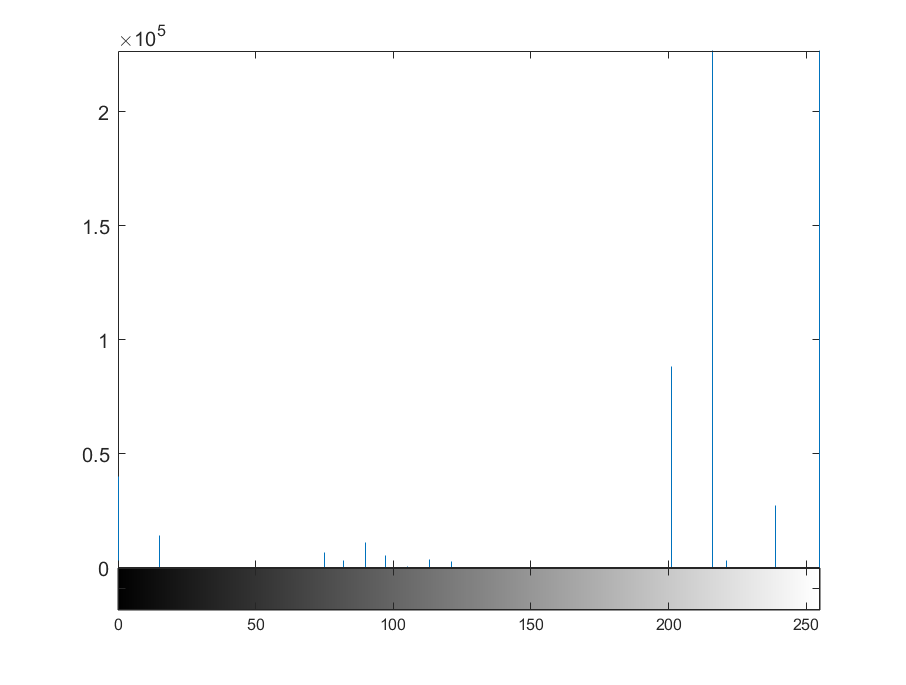

imhist(Igr);


thisIntensity = impixel(Igr, 50, 50);
thisIntensity

thisIntensity =    255   255   255


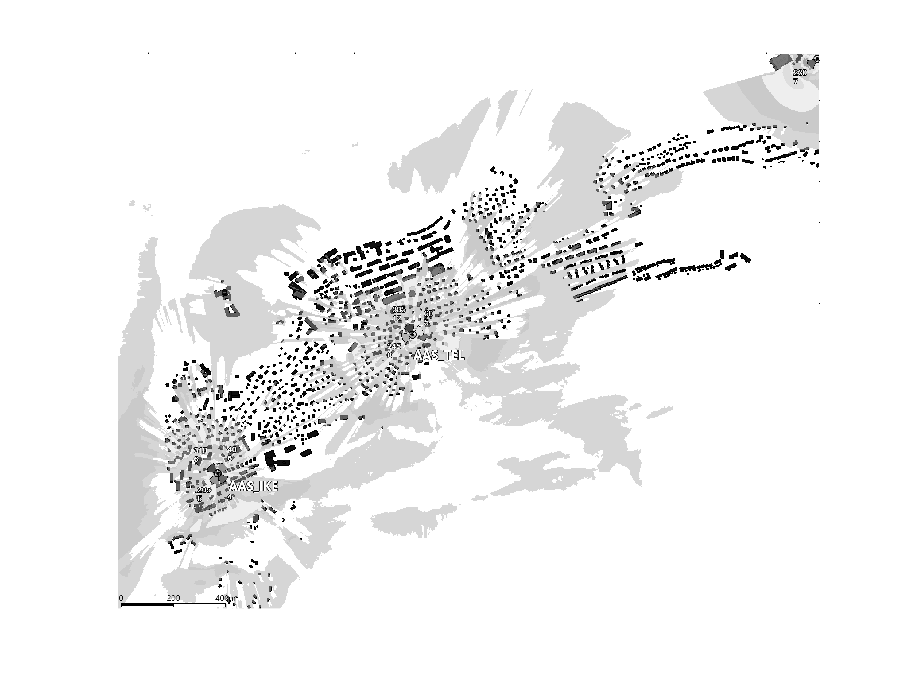

[X, map] = gray2ind(Igr, 64);
imshow(X, map);

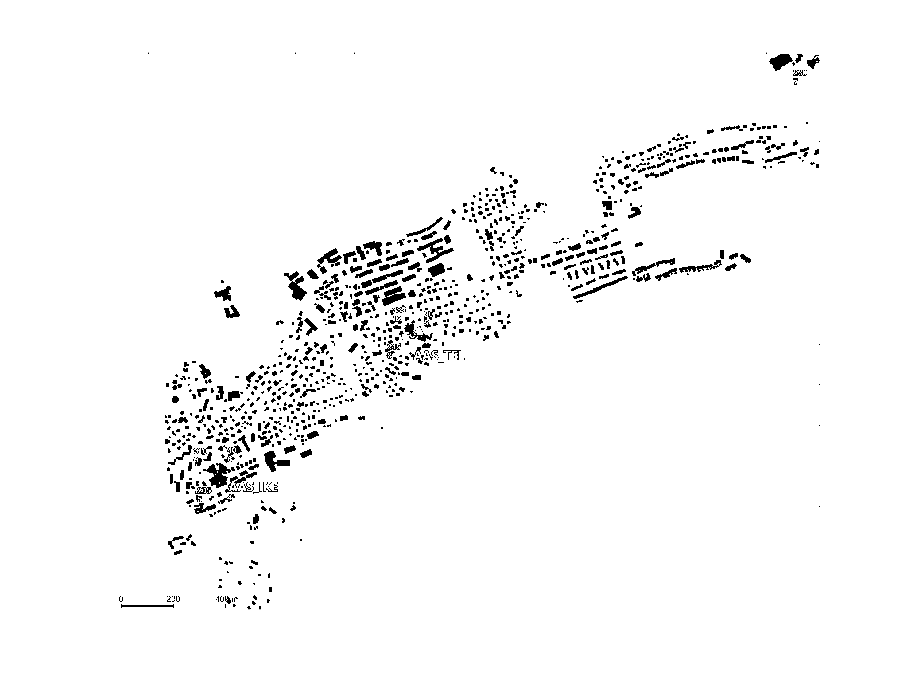

indices = find(abs(X)>40);
X(indices) = 255;

indices2 = find(abs(X)<40);
X(indices2) = 0;

imshow(X, map);

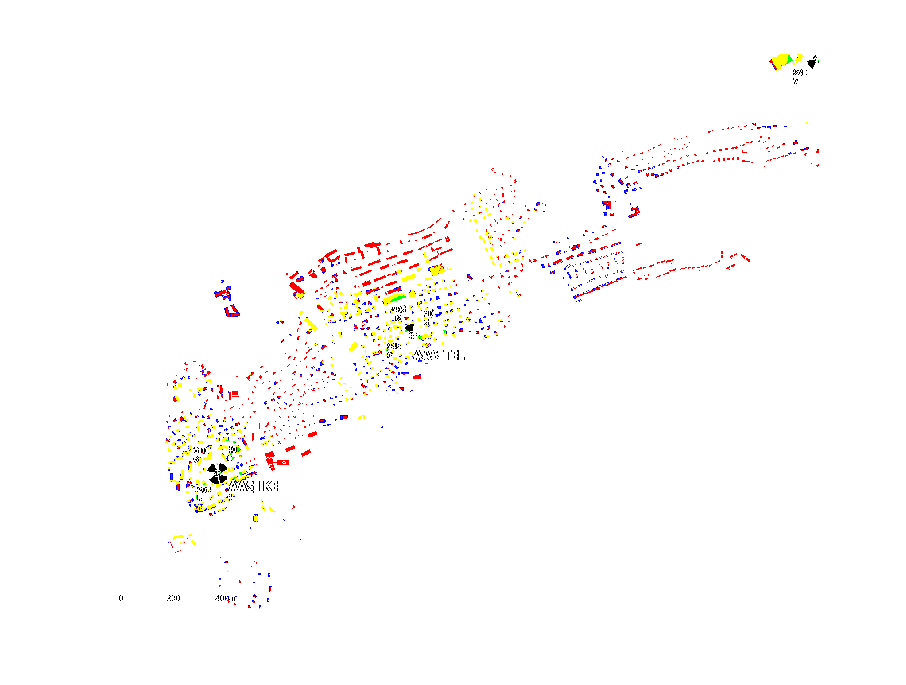

%{
X;
[row,col] = find(abs(X)<1);
[row,col] ;
rgbColor = impixel(mc, col, row);

Threshold = -100;
Penloss = -0;
F = zeros(min(size(X)),max(size(X)),3);
F(:,:,1) = X(:,:);
F(:,:,2) = X(:,:);
F(:,:,3) = X(:,:);
NewImage = X;
GreenCount = 0;
RedCount = 0;
redC =0;
brownC = 0;
YelC = 0;
GreenC = 0;
LightBlueC  = 0;
MidBlueC = 0;
DarkBlueC = 0;
for k = 1:max(size(rgbColor))
    
            if rgbColor(k,1) == 128 && rgbColor(k,2) == 0
                redC = redC +1;
                Signal = -70+Penloss;
                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                  
                if Signal < Threshold;
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;
                   RedCount = RedCount+1;
                else
                   GreenCount = GreenCount+1;

                end
            end

            if rgbColor(k,1) == 127 && (rgbColor(k,2) == 84 || rgbColor(k,2) == 63) || rgbColor(k,2) == 97 || (rgbColor(k,1) == 127 && (rgbColor(k,2) == 84 || rgbColor(k,2) == 63 || rgbColor(k,2) == 94) && rgbColor(k,3) == 63)
                Signal = -80+Penloss;
                brownC = brownC +1;
                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                if Signal < Threshold;
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;
                   RedCount = RedCount+1;
                else
                   GreenCount = GreenCount+1;
                end    
            end

            if (rgbColor(k,1) == 128 || rgbColor(k,1) == 127) && (rgbColor(k,2) == 128 || rgbColor(k,2) == 127)
                Signal = -90+Penloss;
                YelC = YelC +1;
                                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                if Signal < Threshold;
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;
                   RedCount = RedCount+1;
                else
                   GreenCount = GreenCount+1;
                end
            end
            if rgbColor(k,1) == 0 && rgbColor(k,2) == 128 && (rgbColor(k,3) == 0 || rgbColor(k,3) == 63)
                Signal = -100+Penloss;
                GreenC = GreenC +1;
                                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                if Signal < Threshold;
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;
                   RedCount = RedCount+1;
                else
                    GreenCount = GreenCount+1;

                end
            end

            if rgbColor(k,2) == 128 && rgbColor(k,3) == 128
                Signal = -110+Penloss;
                LightBlueC = LightBlueC +1;
                                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                if Signal < Threshold;
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;
                   RedCount = RedCount+1;
                else
                    GreenCount = GreenCount+1;

                end
            end
            if rgbColor(k,2) == 128 && rgbColor(k,3) == 191
                Signal = -120+Penloss;
                MidBlueC = MidBlueC +1;
                                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                if Signal < Threshold;
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;
                   RedCount = RedCount+1;
                else
                    GreenCount = GreenCount+1;
                    
                end
            end
            if rgbColor(k,3) == 128 && rgbColor(k,2) == 0
                Signal = -130+Penloss;
                DarkBlueC = DarkBlueC +1;
                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                if Signal < Threshold;
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;
                   RedCount = RedCount+1;
                else
                    GreenCount = GreenCount+1;
                end
            end

            if rgbColor(k,1) == 0 && rgbColor(k,2) == 0 && rgbColor(k,3) == 0
                NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 255;
                   %Ingen count her, fordi hvis det er rent sort, skal det
                   %ikke tælle med i det overordnede antal af bygninger
            end

end
%}
X;
[row,col] = find(abs(X)<1);
[row,col] ;
rgbColor = impixel(mc, col, row);

Threshold = -115;
Penloss2Lag = -14.1;
Penloss3Lag = -28.2;
F = zeros(min(size(X)),max(size(X)),3);
F(:,:,1) = X(:,:);
F(:,:,2) = X(:,:);
F(:,:,3) = X(:,:);
NewImage = X;
GreenCount = 0;
RedCount = 0;
YelCount = 0;
BlueCount = 0;
redC =0;
brownC = 0;
YelC = 0;
GreenC = 0;
LightBlueC  = 0;
MidBlueC = 0;
DarkBlueC = 0;
for k = 1:max(size(rgbColor))
    
            if rgbColor(k,1) == 128 && rgbColor(k,2) == 0
                redC = redC +1;
                Signal = -70;

                  
                if (Signal+Penloss3Lag) > Threshold %3lags
                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                   GreenCount = GreenCount+1;
                elseif (Signal+Penloss2Lag) > Threshold %2lags
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                   YelCount = YelCount+1;
                elseif (Signal) > Threshold %Outdoor uden pen
                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 255;
                   BlueCount = BlueCount+1;
                else % nothing
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;
                   RedCount = RedCount+1;

                end
            end

            if rgbColor(k,1) == 127 && (rgbColor(k,2) == 84 || rgbColor(k,2) == 63) || rgbColor(k,2) == 97 || (rgbColor(k,1) == 127 && (rgbColor(k,2) == 84 || rgbColor(k,2) == 63 || rgbColor(k,2) == 94) && rgbColor(k,3) == 63)
                Signal = -80;
                brownC = brownC +1;
                if (Signal+Penloss3Lag) > Threshold %3lags
                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                   GreenCount = GreenCount+1;
                elseif (Signal+Penloss2Lag) > Threshold %2lags
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                   YelCount = YelCount+1;
                elseif (Signal) > Threshold %Outdoor uden pen
                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 255;
                   BlueCount = BlueCount+1;
                else % nothing
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;
                   RedCount = RedCount+1;

                end   
            end

            if (rgbColor(k,1) == 128 || rgbColor(k,1) == 127) && (rgbColor(k,2) == 128 || rgbColor(k,2) == 127)
                Signal = -90;
                YelC = YelC +1;
                if (Signal+Penloss3Lag) > Threshold %3lags
                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                   GreenCount = GreenCount+1;
                elseif (Signal+Penloss2Lag) > Threshold %2lags
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                   YelCount = YelCount+1;
                elseif (Signal) > Threshold %Outdoor uden pen
                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 255;
                   BlueCount = BlueCount+1;
                else % nothing
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;
                   RedCount = RedCount+1;

                end
            end
            if rgbColor(k,1) == 0 && rgbColor(k,2) == 128 && (rgbColor(k,3) == 0 || rgbColor(k,3) == 63)
                Signal = -100;
                GreenC = GreenC +1;
                if (Signal+Penloss3Lag) > Threshold %3lags
                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                   GreenCount = GreenCount+1;
                elseif (Signal+Penloss2Lag) > Threshold %2lags
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                   YelCount = YelCount+1;
                elseif (Signal) > Threshold %Outdoor uden pen
                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 255;
                   BlueCount = BlueCount+1;
                else % nothing
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;
                   RedCount = RedCount+1;

                end
            end

            if rgbColor(k,2) == 128 && rgbColor(k,3) == 128
                Signal = -110;
                LightBlueC = LightBlueC +1;
                if (Signal+Penloss3Lag) > Threshold %3lags
                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                   GreenCount = GreenCount+1;
                elseif (Signal+Penloss2Lag) > Threshold %2lags
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                   YelCount = YelCount+1;
                elseif (Signal) > Threshold %Outdoor uden pen
                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 255;
                   BlueCount = BlueCount+1;
                else % nothing
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;
                   RedCount = RedCount+1;

                end
            end
            if rgbColor(k,2) == 128 && rgbColor(k,3) == 191
                Signal = -120;
                MidBlueC = MidBlueC +1;
                if (Signal+Penloss3Lag) > Threshold %3lags
                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                   GreenCount = GreenCount+1;
                elseif (Signal+Penloss2Lag) > Threshold %2lags
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                   YelCount = YelCount+1;
                elseif (Signal) > Threshold %Outdoor uden pen
                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 255;
                   BlueCount = BlueCount+1;
                else % nothing
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;
                   RedCount = RedCount+1;

                end
            end
            if rgbColor(k,3) == 128 && rgbColor(k,2) == 0
                Signal = -130;
                DarkBlueC = DarkBlueC +1;
                if (Signal+Penloss3Lag) > Threshold %3lags
                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                   GreenCount = GreenCount+1;
                elseif (Signal+Penloss2Lag) > Threshold %2lags
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 0;
                   YelCount = YelCount+1;
                elseif (Signal) > Threshold %Outdoor uden pen
                   F(row(k),col(k),1) = 0;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 255;
                   BlueCount = BlueCount+1;
                else % nothing
                   NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 0;
                   F(row(k),col(k),3) = 0;
                   RedCount = RedCount+1;

                end
            end

            if rgbColor(k,1) == 0 && rgbColor(k,2) == 0 && rgbColor(k,3) == 0
                NewImage(row(k),col(k)) = 255;
                   F(row(k),col(k),1) = 255;
                   F(row(k),col(k),2) = 255;
                   F(row(k),col(k),3) = 255;
                   %Ingen count her, fordi hvis det er rent sort, skal det
                   %ikke tælle med i det overordnede antal af bygninger
            end

end
imshow(F,map)

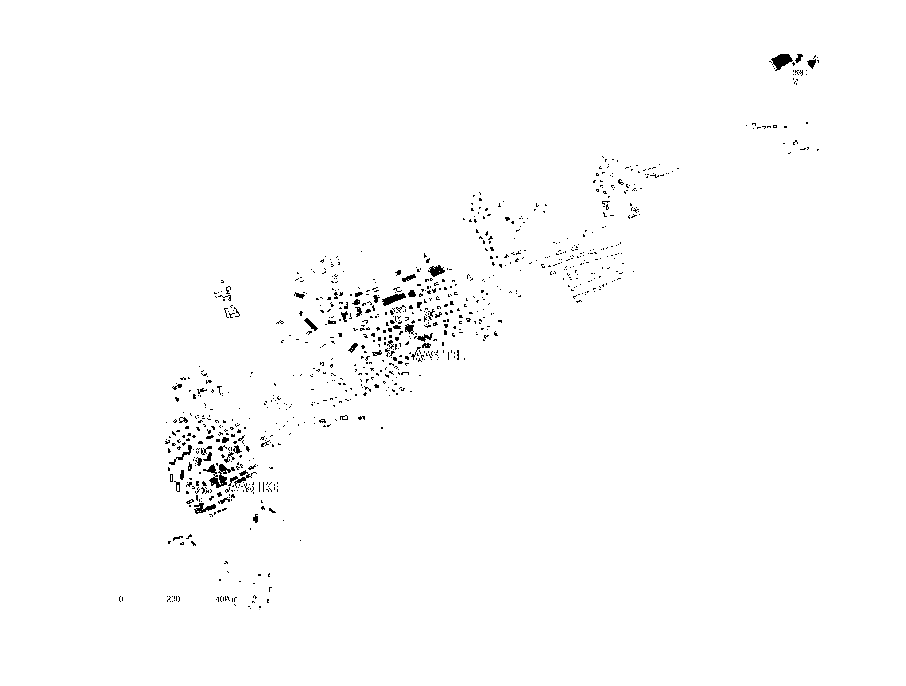

imshow(NewImage);

Totalcount = RedCount+GreenCount+YelCount+BlueCount

Totalcount = 48056

Y = [GreenCount/Totalcount*100 YelCount/Totalcount*100 BlueCount/Totalcount*100 RedCount/Totalcount*100]

Y =     1.6689   34.9134   23.1855   40.2322


Names = {'3LagPenLoss'; '2LagPenLoss'; 'Outdoor/Ingen PenLoss'; 'Intet signal';}

Names = 4×1 cell array
    {'3LagPenLoss'          }
    {'2LagPenLoss'          }
    {'Outdoor/Ingen PenLoss'}
    {'Intet signal'         }


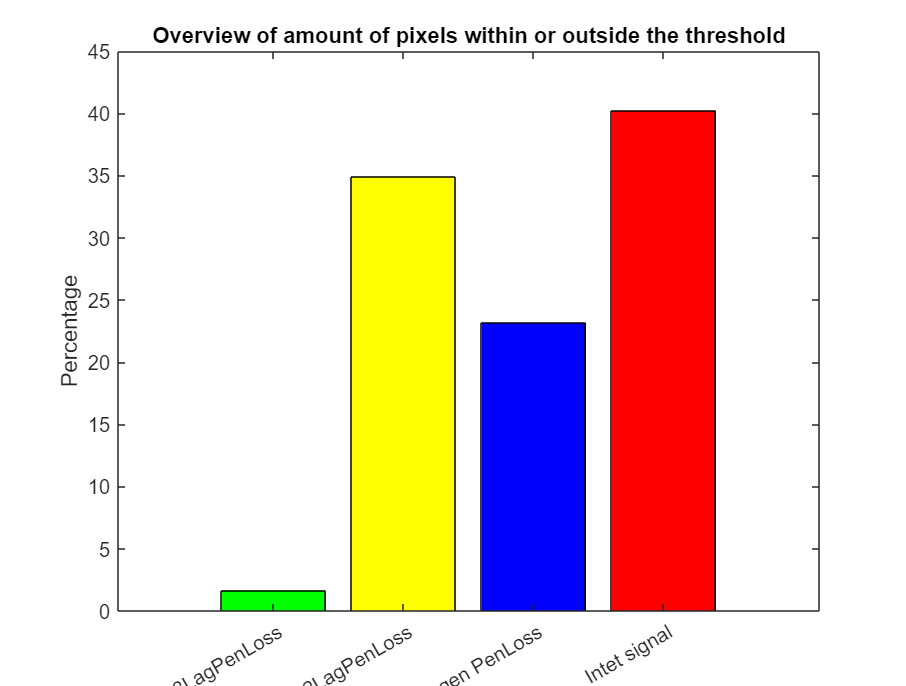

X = [1 2 3 4];
b = bar(X,Y);
b.FaceColor = 'flat';
b.CData(1,:) = [0 1 0];
b.CData(2,:) = [1 1 0];
b.CData(3,:) = [0 0 1];
b.CData(4,:) = [1 0 0];
set(gca,'xtick',[1:4],'xticklabel',Names);
ylabel('Percentage')
title('Overview of amount of pixels within or outside the threshold -115dbm')

%text(1:length(Y),Y,num2str(Y')+"%",'vert','bottom','horiz','center'); 
%box off

redC

redC = 31

brownC

brownC = 771

YelC

YelC = 6483

GreenC

GreenC = 10295

LightBlueC

LightBlueC = 11142

MidBlueC

MidBlueC = 5334

DarkBlueC

DarkBlueC = 14000

y = [redC brownC YelC GreenC LightBlueC MidBlueC DarkBlueC]

y =           31         771        6483       10295       11142        5334       14000


x = [-70 -80 -90 -100 -110 -120 -130];
y = y./sum(y)

y =     0.0006    0.0160    0.1349    0.2142    0.2319    0.1110    0.2913


y1 = y*100

y1 =     0.0645    1.6044   13.4905   21.4229   23.1855   11.0996   29.1327


sum(y)

ans = 1

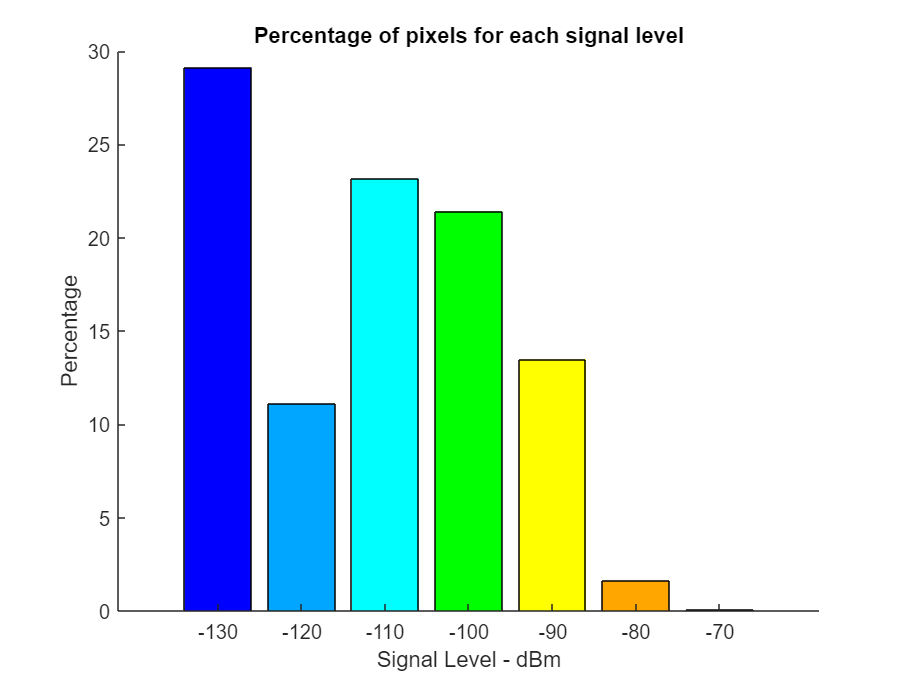

b = bar(x,y1);
b.FaceColor = 'flat';
b.CData(1,:) = [0 0 1];
b.CData(2,:) = [0 .65 1];
b.CData(3,:) = [0 1 1];
b.CData(4,:) = [0 1 0];
b.CData(5,:) = [1 1 0];
b.CData(6,:) = [1 .65 0];
b.CData(7,:) = [1 0 0];
xlabel('Signal Level - dBm')
ylabel('Percentage')
title('Percentage of pixels for each signal level')
text(length(y1):-1:1,y1,num2str(y1'),'vert','bottom','horiz','center'); 
box off